%Select file to access:
filename_EKF = '/Users/ferialmeyer/Documents/RESULTS/EKFData/EKFData_9.csv';
filename_Encoder = '/Users/ferialmeyer/Documents/RESULTS/EncoderData/EncoderData_9.csv';
filename_CamData = '/Users/ferialmeyer/Documents/RESULTS/CameraCountData/CameraCountData_9.csv';

%Reading files as tables
dataTable_EKF = readtable(filename_EKF);
dataTable_Encoder = readtable(filename_Encoder);
dataTable_CamData = readtable(filename_CamData);

%EKF data
%Position:
xPos_EKF = dataTable_EKF.X_Pos;
yPos_EKF = dataTable_EKF.Y_Pos;
zPos_EKF = dataTable_EKF.Z_Pos;
xVel_EKF = dataTable_EKF.X_Vel;
yVel_EKF = dataTable_EKF.Y_Vel;
zVel_EKF = dataTable_EKF.Z_Vel;

%Orientation:
q0_EKF = dataTable_EKF.q0;
qx_EKF = dataTable_EKF.qx;
qy_EKF = dataTable_EKF.qy;
qz_EKF = dataTable_EKF.qz;

%Graphing orientation
eulZYX_EKF = rad2deg(quat2eul([q0_EKF(:) qx_EKF(:) qy_EKF(:) qz_EKF(:)]));

xOmega_EKF = dataTable_EKF.omega_x;
yOmega_EKF = dataTable_EKF.omega_y;
zOmega_EKF = dataTable_EKF.omega_z;

%Time and refreshrates:
runtime_EKF = dataTable_EKF.EKFElapsedTime;
hz_EKF = dataTable_EKF.RefreshRate;
timestamp_EKF = dataTable_EKF.TimeStamps;

%Encoder data conversion
angPos_enc = dataTable_Encoder.Encoder_Reading;
timestamp_enc = dataTable_Encoder.Timestamp + seconds(0.15)

timestamp_enc = 1066×1 duration array
   12:35:24.172875
   12:35:24.271108
   12:35:24.373478
   12:35:24.471921
   12:35:24.574190
   12:35:24.672612
   12:35:24.770681
   12:35:24.873021
   12:35:24.971862
   12:35:25.073873
   12:35:25.172196
   12:35:25.270509
   12:35:25.372934
   12:35:25.471214
   12:35:25.573730
   12:35:25.672166
   12:35:25.774689
   12:35:25.873182
   12:35:25.971516
   12:35:26.073618
   12:35:26.171858
   12:35:26.274440
   12:35:26.372682
   12:35:26.470851
   12:35:26.573295
   12:35:26.672001
   12:35:26.774256
   12:35:26.872633
   12:35:26.974707
   12:35:27.073453



%Converting the timestamps
% Step 1: Identify the first EKF timestamp
firstEKFTime = timestamp_EKF(1);
lastEKFTIme = timestamp_EKF(length(timestamp_EKF))

lastEKFTIme = duration
   12:36:44.658



% Step 2: Create a logical index for encoder timestamps that are after the first EKF timestamp
validEncoderIndices_AFTER = (timestamp_enc >= firstEKFTime);
validEncoderIndices_BEFORE = (timestamp_enc <= lastEKFTIme);
validEncoderIndices = (validEncoderIndices_AFTER == validEncoderIndices_BEFORE);
% Step 3: Filter the encoder data and timestamps
filtered_angPos_enc = angPos_enc(validEncoderIndices, :); % Assuming you have corresponding encoder data
filtered_timestamp_enc = timestamp_enc(validEncoderIndices,:);

%Step 4: Set runtime of the encoder
runtime_enc = seconds(filtered_timestamp_enc(:)-filtered_timestamp_enc(1));


eulZYX_enc = [filtered_angPos_enc(:) zeros(length(filtered_angPos_enc),1) zeros(length(filtered_angPos_enc),1)];

% Assuming encoderAngles is your array of angles from the encoder [0, 360]
eulZYX_enc_wrapped = zeros(length(filtered_angPos_enc),3);
wrappedAngles = zeros(length(filtered_angPos_enc),1);
for i = 1:3
    encoderAngles = eulZYX_enc(:,i); % Your data here
    wrappedAngles = encoderAngles;
    wrappedAngles(encoderAngles > 180) = encoderAngles(encoderAngles > 180) - 360;
    if i == 1
        eulZYX_enc_wrapped(:,i) = wrappedAngles;
    elseif i == 2
        eulZYX_enc_wrapped(:,i) = wrappedAngles;
    else
        eulZYX_enc_wrapped(:,i) = wrappedAngles;
    end
end

%Calculating Position
l = 0.482

l = 0.4820

xPos_enc_1 = -l*sin(deg2rad(filtered_angPos_enc(:))) + 0.005; %Look at pose at platform
yPos_enc_1 = l*cos(deg2rad(filtered_angPos_enc(:))) - l - 0.0025;
zPos_enc_1 = zeros(length(filtered_angPos_enc),1) - 0.0001;
theta = asin(0.3/2*l);
rad2deg(theta)

ans = 4.1461

R = eul2rotm([0,0,deg2rad(5)]);

Pos3D = R*[xPos_enc_1';yPos_enc_1';zPos_enc_1']

Pos3D =     0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0058   -0.0021   -0.0116   -0.0184   -0.0214   -0.0214   -0.0214   -0.0214   -0.0214   -0.0214   -0.0214   -0.0215   -0.0215   -0.0215   -0.0215   -0.0219   -0.0253   -0.0333   -0.0467   -0.0621
   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0028   -0.0030   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0034   -0.0040   -0.0053 

eul3D = cell(length(eulZYX_enc_wrapped),1)

eul3D = 599×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


for k = 1:length(eulZYX_enc_wrapped)
    eul3D{k} = R*[eul2rotm(deg2rad(eulZYX_enc_wrapped(k,:)))];
    eulZYX_enc_wrapped(k,:) = rad2deg(rotm2eul(eul3D{k}));
    eulZYX_enc_wrapped(k,3) = eulZYX_enc_wrapped(k,3)-2;
    eulZYX_enc_wrapped(k,2) = eulZYX_enc_wrapped(k,2)-0.39;
end
xPos_enc = Pos3D(1,:);
yPos_enc = Pos3D(2,:);
zPos_enc = Pos3D(3,:);

%xPos RMSE:
xPos_enc_interp = interp1(runtime_enc,xPos_enc,runtime_EKF,'linear','extrap');
validIdx = ~isnan(xPos_EKF);
rmse_x = sqrt(mean((xPos_EKF(validIdx) - xPos_enc_interp(validIdx)).^2))

rmse_x = 0.0056


%yPos RMSE:
yPos_enc_interp = interp1(runtime_enc,yPos_enc,runtime_EKF,'linear','extrap');
validIdx = ~isnan(yPos_EKF);
rmse_y = sqrt(mean((yPos_EKF(validIdx) - yPos_enc_interp(validIdx)).^2))

rmse_y = 0.0054


%computing RMSE:
zPos_enc_interp = interp1(runtime_enc,zPos_enc,runtime_EKF,'linear','extrap');
validIdx = ~isnan(zPos_EKF);
rmse_z = sqrt(mean((zPos_EKF(validIdx) - zPos_enc_interp(validIdx)).^2))

rmse_z = 0.0049


rmse_3D = norm([rmse_x rmse_y]) % rmse_z])

rmse_3D = 0.0078


%xPos RMSE:
eulX_enc_interp = interp1(runtime_enc,eulZYX_enc_wrapped(:,3),runtime_EKF,'linear','extrap');
validIdx = ~isnan(eulZYX_EKF(:,3));
rmse_x_angle = sqrt(mean((eulZYX_EKF(validIdx,3) - eulX_enc_interp(validIdx)).^2))

rmse_x_angle = 0.9617


%xPos RMSE:
eulY_enc_interp = interp1(runtime_enc,eulZYX_enc_wrapped(:,2),runtime_EKF,'linear','extrap');
validIdx = ~isnan(eulZYX_EKF(:,2));
rmse_y_angle = sqrt(mean((eulZYX_EKF(validIdx,2) - eulY_enc_interp(validIdx)).^2))

rmse_y_angle = 0.9411


%xPos RMSE:
eulZ_enc_interp = interp1(runtime_enc,eulZYX_enc_wrapped(:,1),runtime_EKF,'linear','extrap');
validIdx = ~isnan(eulZYX_EKF(:,1));
rmse_z_angle = sqrt(mean((eulZYX_EKF(validIdx,1) - eulZ_enc_interp(validIdx)).^2))

rmse_z_angle = 1.3999


rmse_3D_angle = norm([rmse_x_angle rmse_y_angle rmse_z_angle])

rmse_3D_angle = 1.9417

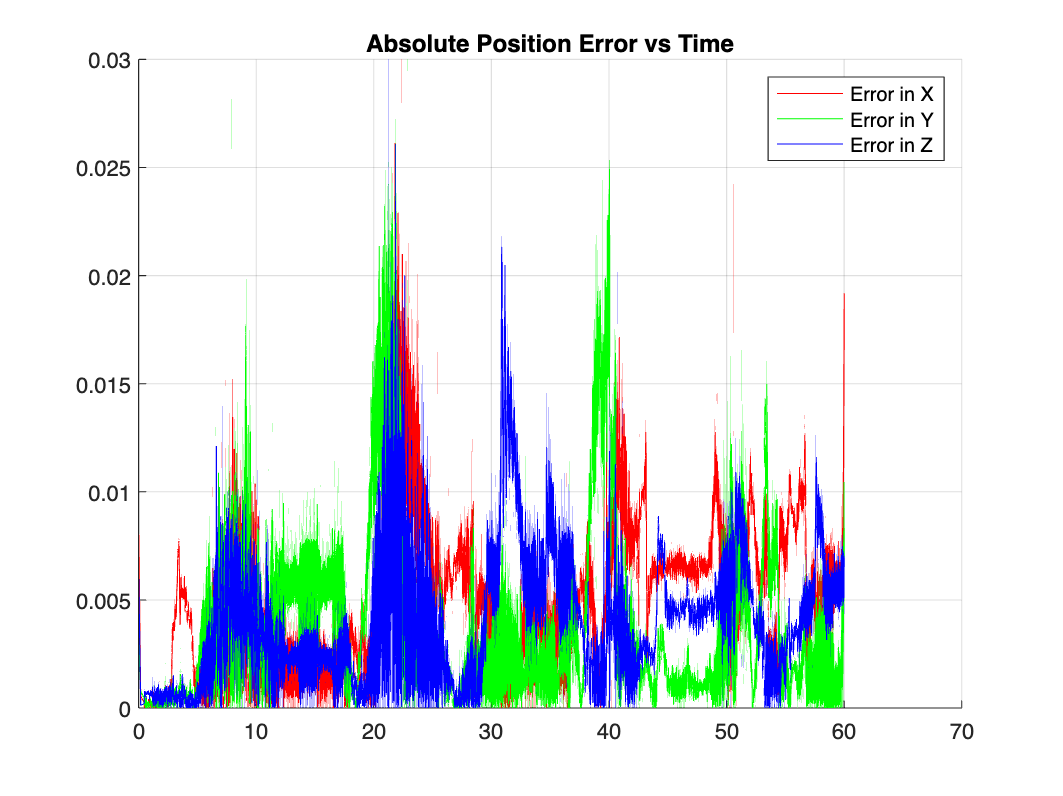



figure(4),clf,grid,hold on
title('Absolute Position Error vs Time')
plot(runtime_EKF,abs(xPos_enc_interp-xPos_EKF),'r-')
plot(runtime_EKF,abs(yPos_enc_interp-yPos_EKF),'g-')
plot(runtime_EKF,abs(zPos_enc_interp-zPos_EKF),'b-')
legend('Error in X','Error in Y','Error in Z')

max(abs(xPos_enc_interp-xPos_EKF))

ans = 0.0261

max(abs(yPos_enc_interp-yPos_EKF))

ans = 0.0249

max(abs(zPos_enc_interp-zPos_EKF))

ans = 0.0261

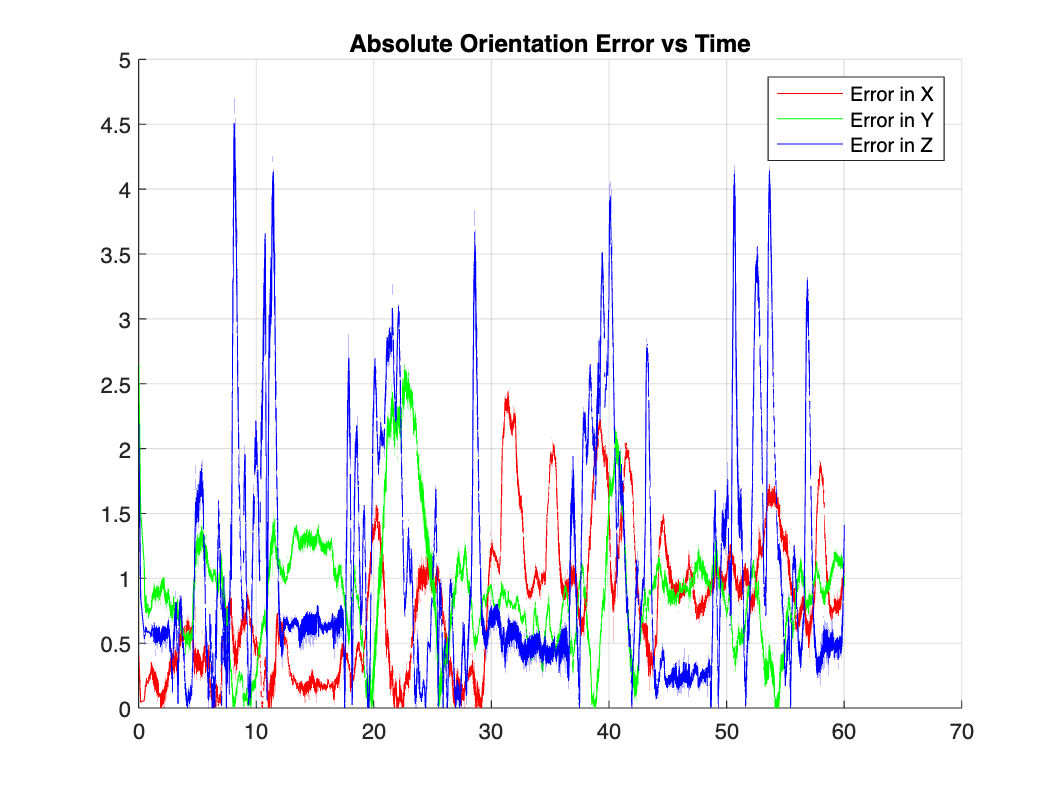


figure(4),clf,grid,hold on
title('Absolute Orientation Error vs Time')
plot(runtime_EKF,abs(eulZYX_EKF(:,3)-eulX_enc_interp),'r-')
plot(runtime_EKF,abs(eulZYX_EKF(:,2)-eulY_enc_interp),'g-')
plot(runtime_EKF,abs(eulZYX_EKF(:,1)-eulZ_enc_interp),'b-')
legend('Error in X','Error in Y','Error in Z')

max(abs(eulZYX_EKF(:,3)-eulX_enc_interp))

ans = 2.4388

max(abs(eulZYX_EKF(:,2)-eulY_enc_interp))

ans = 2.6521

max(abs(eulZYX_EKF(:,1)-eulZ_enc_interp))

ans = 4.5079

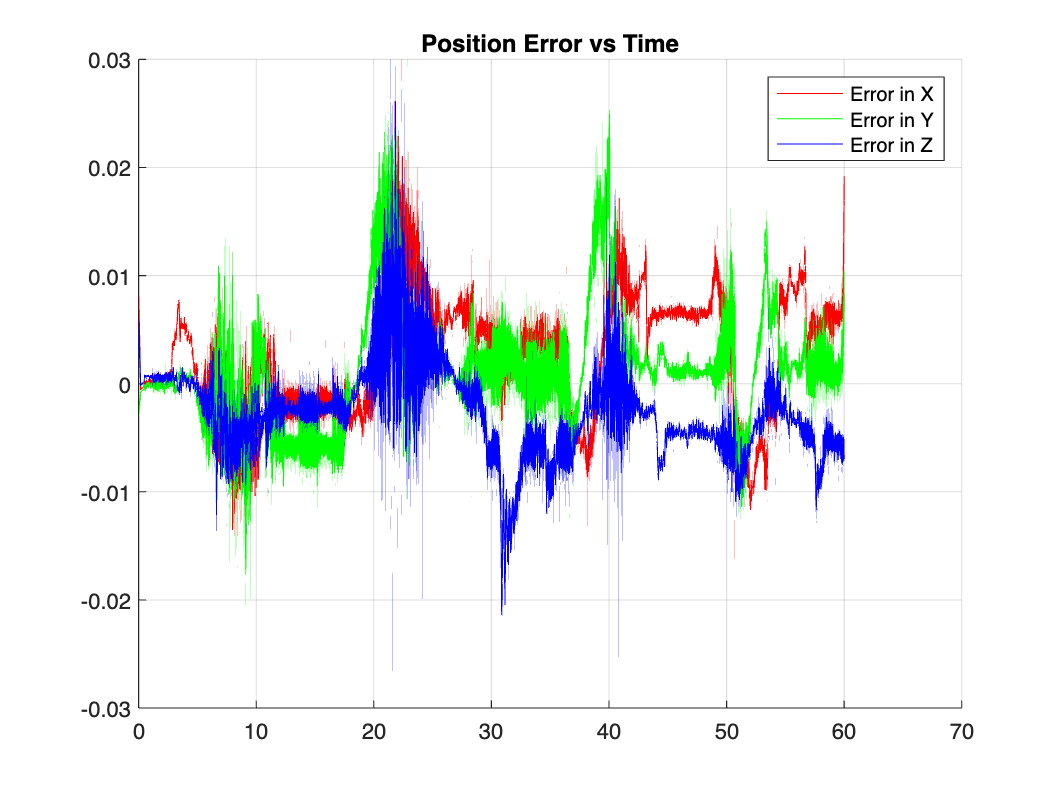



figure(4),clf,grid,hold on
title('Position Error vs Time')
plot(runtime_EKF,(xPos_enc_interp-xPos_EKF),'r-')
plot(runtime_EKF,(yPos_enc_interp-yPos_EKF),'g-')
plot(runtime_EKF,(zPos_enc_interp-zPos_EKF),'b-')
legend('Error in X','Error in Y','Error in Z')

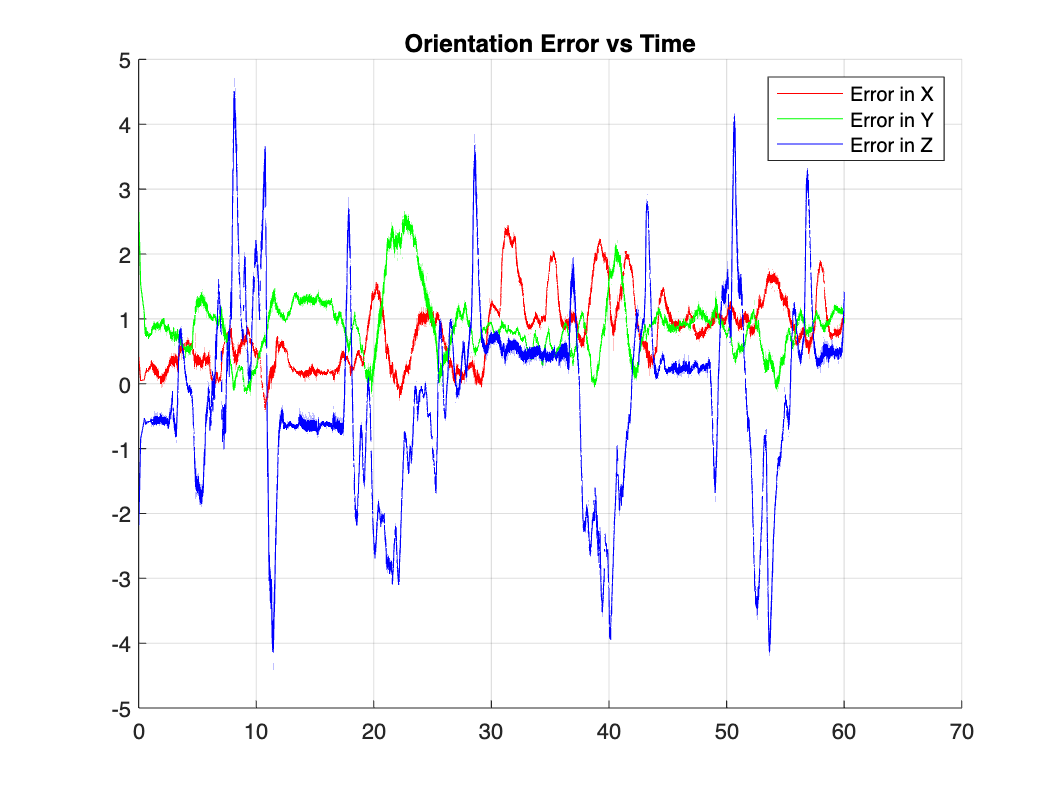



figure(4),clf,grid,hold on
title('Orientation Error vs Time')
plot(runtime_EKF,(eulZYX_EKF(:,3)-eulX_enc_interp),'r-')
plot(runtime_EKF,(eulZYX_EKF(:,2)-eulY_enc_interp),'g-')
plot(runtime_EKF,(eulZYX_EKF(:,1)-eulZ_enc_interp),'b-')
legend('Error in X','Error in Y','Error in Z')

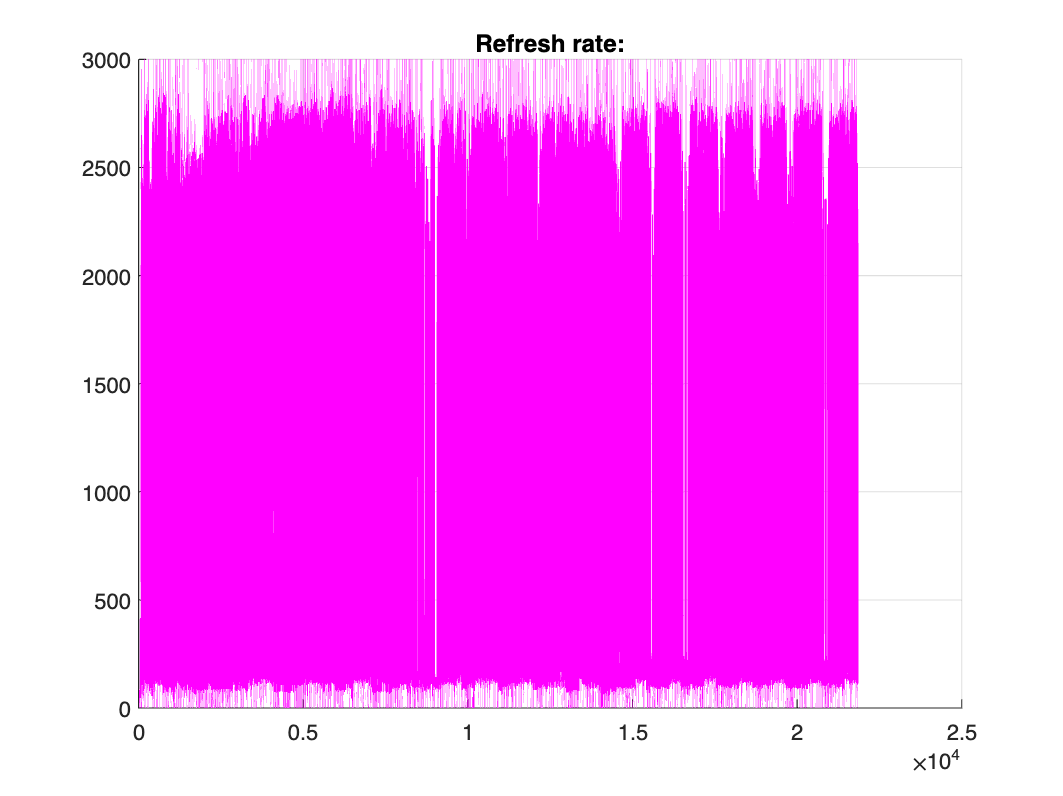



%GRAPHING HZ:
figure(1),clf,grid,hold on
title('Refresh rate:')
plot(linspace(1,length(hz_EKF),length(hz_EKF)),hz_EKF,'m-')

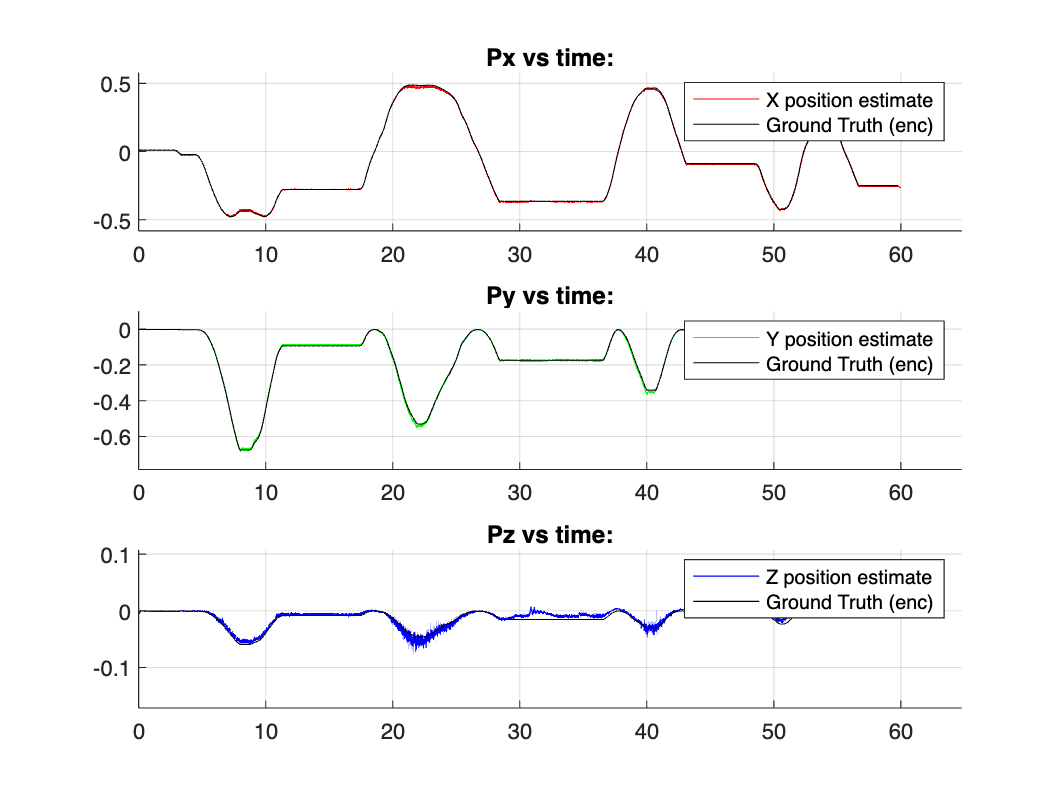



% Create a new figure
figure('Name', 'Position vs Time Plots'), clf
title('Position vs Time Plots')

% Subplot for Xk's X position vs time
subplot(3, 1, 1), grid, hold on
title('Px vs time:')
plot(runtime_EKF, xPos_EKF, 'r-')
plot(runtime_enc,xPos_enc,'k-')
axis([0 runtime_enc(length(runtime_enc))+5 min(xPos_EKF)-0.1 max(xPos_EKF)+0.1])
legend('X position estimate','Ground Truth (enc)')

% Subplot for Xk's Y position vs time
subplot(3, 1, 2), grid, hold on
title('Py vs time:')
plot(runtime_EKF, yPos_EKF, 'g-')
plot(runtime_enc,yPos_enc,'k-')
axis([0 runtime_enc(length(runtime_enc))+5 min(yPos_EKF)-0.1 max(yPos_EKF)+0.1])
legend('Y position estimate','Ground Truth (enc)')

% Subplot for Xk's Z position vs time
subplot(3, 1, 3), grid, hold on
title('Pz vs time:')
plot(runtime_EKF, zPos_EKF, 'b-')
plot(runtime_enc,zPos_enc,'k-')
axis([0 runtime_enc(length(runtime_enc))+5 min(zPos_EKF)-0.1 max(zPos_EKF)+0.1])
legend('Z position estimate','Ground Truth (enc)')

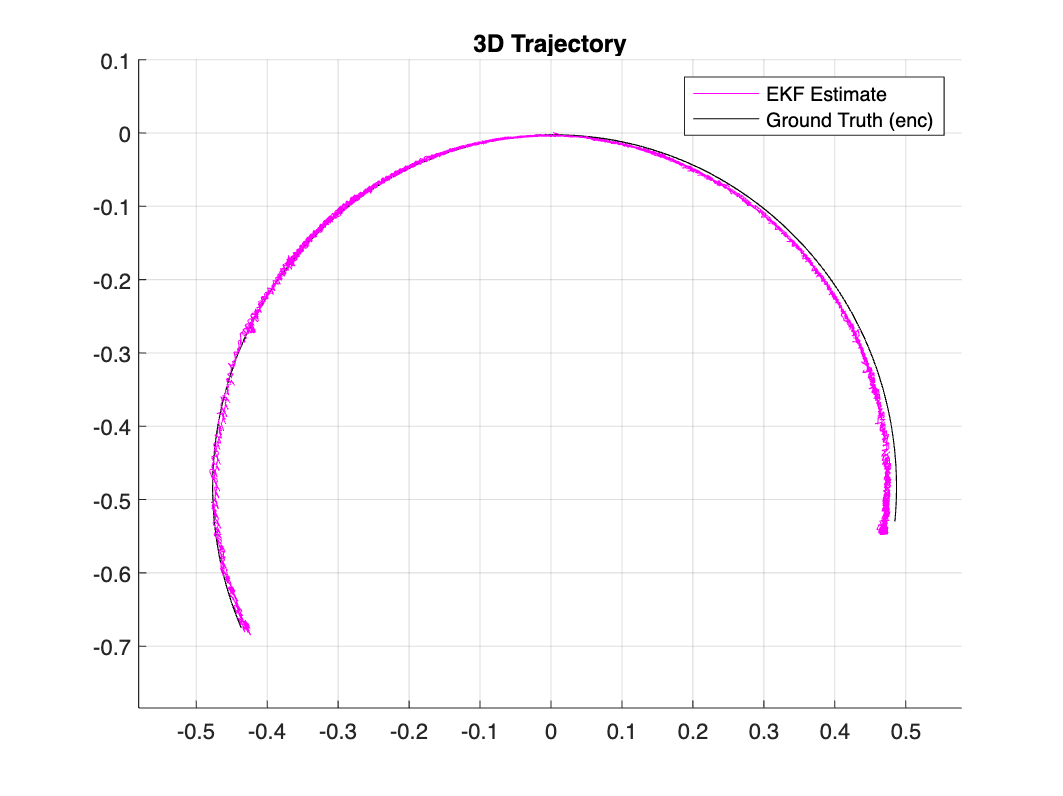


figure('Name','3D Trajectory'),clf,grid, hold on
title('3D Trajectory')
plot3(xPos_EKF,yPos_EKF,zPos_EKF,'m-')
plot3(xPos_enc,yPos_enc,zPos_enc,'k-')
axis([min(xPos_EKF)-0.1 max(xPos_EKF)+0.1 min(yPos_EKF)-0.1 max(yPos_EKF)+0.1 min(zPos_EKF)-0.1 max(zPos_EKF)+0.1])
legend('EKF Estimate','Ground Truth (enc)')
view(2)

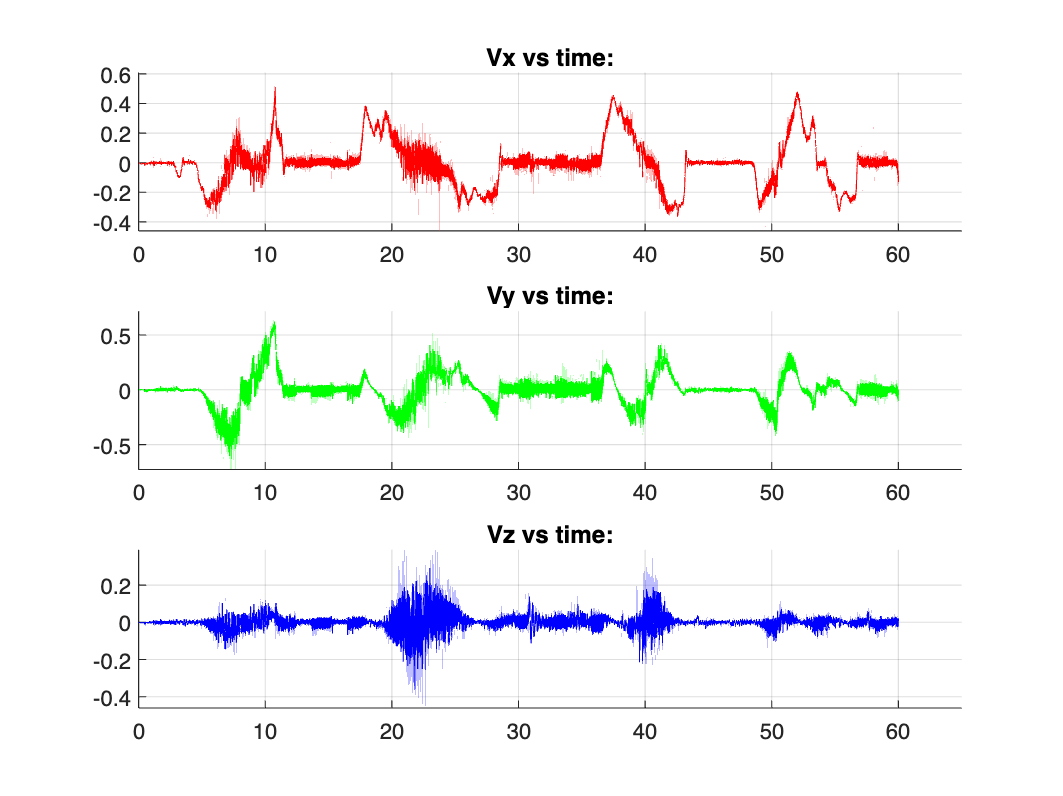


% Create a new figure
figure('Name', 'Velocity vs Time Plots'), clf

% Subplot for Vx vs time
subplot(3, 1, 1), grid, hold on
title('Vx vs time:')
plot(runtime_EKF, xVel_EKF, 'r-')
axis([0 runtime_EKF(length(runtime_EKF))+5 min(xVel_EKF)-0.1 max(xVel_EKF)+0.1])

% Subplot for Vy vs time
subplot(3, 1, 2), grid, hold on
title('Vy vs time:')
plot(runtime_EKF, yVel_EKF, 'g-')
axis([0 runtime_EKF(length(runtime_EKF))+5 min(yVel_EKF)-0.1 max(yVel_EKF)+0.1])

% Subplot for Vz vs time
subplot(3, 1, 3), grid, hold on
title('Vz vs time:')
plot(runtime_EKF, zVel_EKF, 'b-')
axis([0 runtime_EKF(length(runtime_EKF))+5 min(zVel_EKF)-0.1 max(zVel_EKF)+0.1])


Vel3D = zeros(1,length(xVel_EKF));
for k = 1:length(zVel_EKF)
    Vel3D(k) = norm([zVel_EKF(k) yVel_EKF(k) xVel_EKF(k)]);
    angVel3D(k) = norm([xOmega_EKF(k) yOmega_EKF(k) zOmega_EKF(k)]);
end

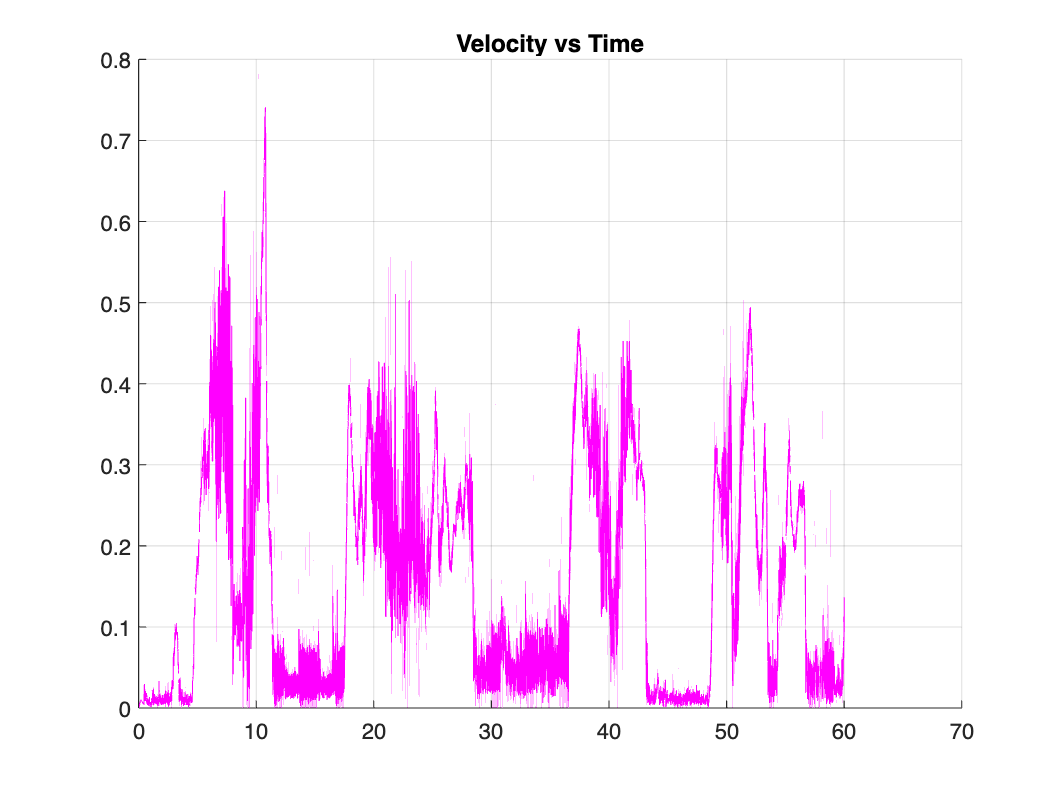

figure(1),clf,grid,hold on
title('Velocity vs Time')
plot(runtime_EKF,Vel3D,'m-')

[M,I] = max(Vel3D)

M = 0.7404

I = 3340

mean(Vel3D(validIdx))

ans = 0.1472

err_3D = norm([xPos_enc_interp(I+2)-xPos_EKF(I+2) yPos_enc_interp(I+2)-yPos_EKF(I+2) zPos_enc_interp(I+2)-zPos_EKF(I+2)])

err_3D = 0.0025

runtime_EKF(I)

ans = 10.7668


[M,I] = max(angVel3D)

M = 1.1200

I = 3394

mean(angVel3D(validIdx))

ans = 0.2763

err_3D = norm([eulZYX_EKF(I,3)-eulX_enc_interp(I) eulZYX_EKF(I,2)-eulY_enc_interp(I) eulZYX_EKF(I,2)-eulY_enc_interp(I)])

err_3D = 1.1489

runtime_EKF(I)

ans = 10.9039


% Create a new figure
figure('Name', 'Rotation vs Time Plots'), clf

% Subplot for rotation in x-axis vs time
subplot(3, 1, 1), grid, hold on
title('Rotation in x-axis (deg) vs time:')
plot(runtime_EKF, eulZYX_EKF(:,3), 'r-')
plot(runtime_enc,eulZYX_enc_wrapped(:,3),'k-')
axis([0 runtime_EKF(length(runtime_EKF))+5 min(eulZYX_EKF(:,3))-20 max(eulZYX_EKF(:,3))+20])
legend('Rotation in x estimate','Ground Truth (enc)')

% Subplot for rotation in y-axis vs time
subplot(3, 1, 2), grid, hold on
title('Rotation in y-axis (deg) vs time:')
plot(runtime_EKF, eulZYX_EKF(:,2), 'g-')
plot(runtime_enc, eulZYX_enc_wrapped(:,2), 'k-')
axis([0 runtime_EKF(length(runtime_EKF))+5 min(eulZYX_EKF(:,2))-20 max(eulZYX_EKF(:,2))+20])
legend('Rotation in y estimate','Ground Truth (enc)')

% Subplot for rotation in z-axis vs time
subplot(3, 1, 3), grid, hold on
title('Rotation in z-axis (deg) vs time:')
plot(runtime_EKF, eulZYX_EKF(:,1), 'b-')
plot(runtime_enc, eulZYX_enc_wrapped(:,1), 'k-')
axis([0 runtime_EKF(length(runtime_EKF))+5 min(eulZYX_EKF(:,1))-20 max(eulZYX_EKF(:,1))+20])
legend('Rotation in z estimate','Ground Truth (enc)')
% Create a new figure
figure('Name', 'Rotational velocity vs Time Plots'), clf

% Subplot for Vx vs time
subplot(3, 1, 1), grid, hold on
title('Omega_x vs time:')
plot(runtime_EKF, xOmega_EKF, 'r-')
axis([0 runtime_EKF(length(runtime_EKF))+5 min(xOmega_EKF)-0.1 max(xOmega_EKF)+0.1])

% Subplot for Vy vs time
subplot(3, 1, 2), grid, hold on
title('Omega_y vs time:')
plot(runtime_EKF, yOmega_EKF, 'g-')
axis([0 runtime_EKF(length(runtime_EKF))+5 min(yOmega_EKF)-0.1 max(yOmega_EKF)+0.1])

% Subplot for Vz vs time
subplot(3, 1, 3), grid, hold on
title('Omega_z vs time:')
plot(runtime_EKF, zOmega_EKF, 'b-')
axis([0 runtime_EKF(length(runtime_EKF))+5 min(zOmega_EKF)-0.1 max(zOmega_EKF)+0.1])